# Fit Second Order With Optimization

Fit parameters $K_p$ and $\tau_p$ from a first order process:


$$G_1(s)=\frac{K_p}{\tau_p \, s + 1}$$


The first order process is in parallel with another first order process:


$$G_2(s)=\frac{-2}{s+1}$$


The combined system has a second order response with data points sampled at 0.5 second intervals from a step input change of 2.0.

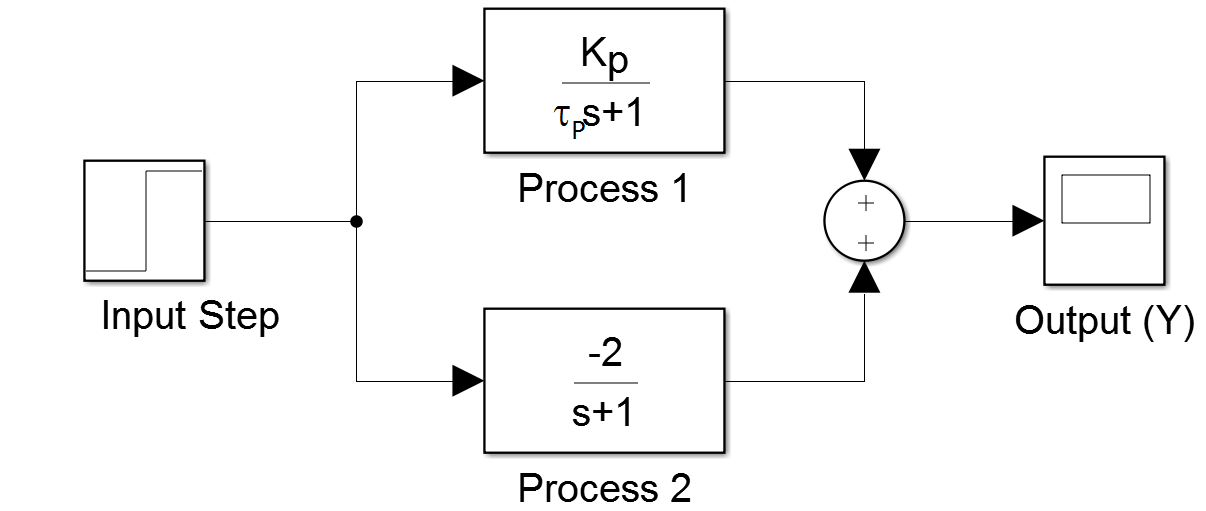

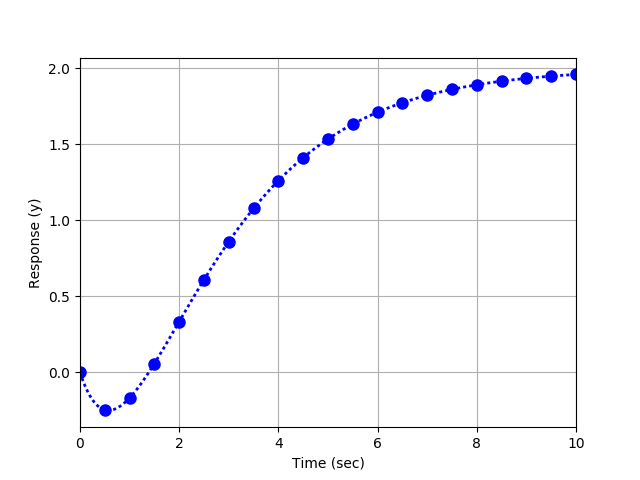

 [**View data file**](https://apmonitor.com/pdc/uploads/Main/data_2nd_order.txt)

### **Read Data**

data = readmatrix('https://apmonitor.com/pdc/uploads/Main/data_2nd_order.txt')
time = data(:,1).';
y = data(:,2).';

Use optimization to minimize the difference between a predicted response and the 21 measured values.

% Y(s) = Kp/(taup * s + 1) * 2/s + -2 / (s+1) * 2/s
y_sim = @(t, Kp, taup)2*Kp * (1-exp(-t/taup))-4*(1-exp(-t))
objective_fn = @(p)sum((y_sim(time, p(1), p(2))-y).^2)

guess = [1;1];
optimized_params = fminsearch(objective_fn, guess);
Kp = optimized_params(1)
taup = optimized_params(2)
y_i = y_sim(time, 1, 1)
y_f = y_sim(time, Kp,taup)

figure()
plot(time, y,'b.','DisplayName','Process Data')
hold on
plot(time, y_i,'r--','DisplayName','Initial Parameters')
hold on
plot(time, y_f,'k--','DisplayName','Regressed Parameters')
hold off
ylabel("Output")
xlabel("Time")
legend("Location","southeast")

### Hint:

The system could be represented as $y(s) =  + \left(\frac{K_p}{\tau_ps+1}\right)\frac{2}{s} +\left(\frac{-2}{s+1}\right)\frac{2}{s} $. Use the Laplace Tables in lesson 24 to manipulate this equation into the time domain ($y(t)$). Then, $K_p$ and $\tau_p$ can be solved for as the only unknowns using `fminsearch` or `fmincon`.

Show $y(t)$ form:

showFormula(false)

Show Solution:

viewSolution(false)

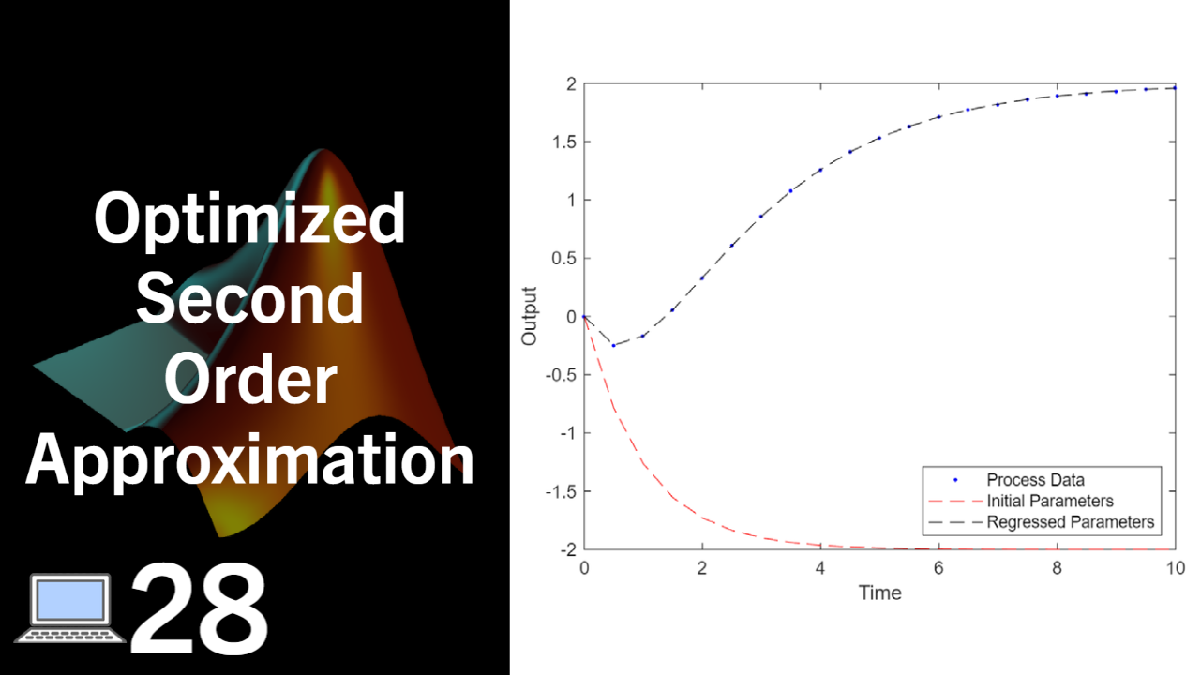

### [View Solution Video](https://youtu.be/6ov-l_AsY9c)

function showFormula(show)
if show
    disp('y(t) = 2*Kp * (1-e^(-t/taup))-4*(1-e^(-t))')
end
end

function viewSolution(view)
if view
	disp("y_sim = @(t, Kp, taup)2*Kp * (1-exp(-t/taup))-4*(1-exp(-t))" + newline + ...
	     "objective_fn = @(p)sum((y_sim(time, p(1), p(2))-y).^2)" + newline + ...
	     "" + newline + ...
	     "guess = [1;1];" + newline + ...
	     "optimized_params = fminsearch(objective_fn, guess);" + newline + ...
	     "Kp = optimized_params(1);" + newline + ...
	     "taup = optimized_params(2);" + newline + ...
	     "y_i = y_sim(time, 1, 1)" + newline + ...
	     "y_f = y_sim(time, Kp,taup)" + newline + ...
	     "" + newline + ...
	     "figure()" + newline + ...
	     "plot(time, y,'b.','DisplayName','Process Data')" + newline + ...
	     "hold on" + newline + ...
	     "plot(time, y_i,'r--','DisplayName','Initial Parameters')" + newline + ...
	     "hold on" + newline + ...
	     "plot(time, y_f,'k--','DisplayName','Regressed Parameters')" + newline + ...
	     "hold off" + newline + ...
	 "end")
end
end